% setting
folder = 'C:\Users\bear\Desktop\figure 4';  
filename = 'liver_temp.csv'; 
imagename = 'crop_distance';
extension = '.tif';
num_channel = 7;
outname = 'liver.csv';

table = readtable(filename);
table_copy = table;
multichannel = import4d(folder, imagename, extension, num_channel);

Finished importing channel 1
Finished importing channel 2
Finished importing channel 3
Finished importing channel 4
Finished importing channel 5
Finished importing channel 6
Finished importing channel 7


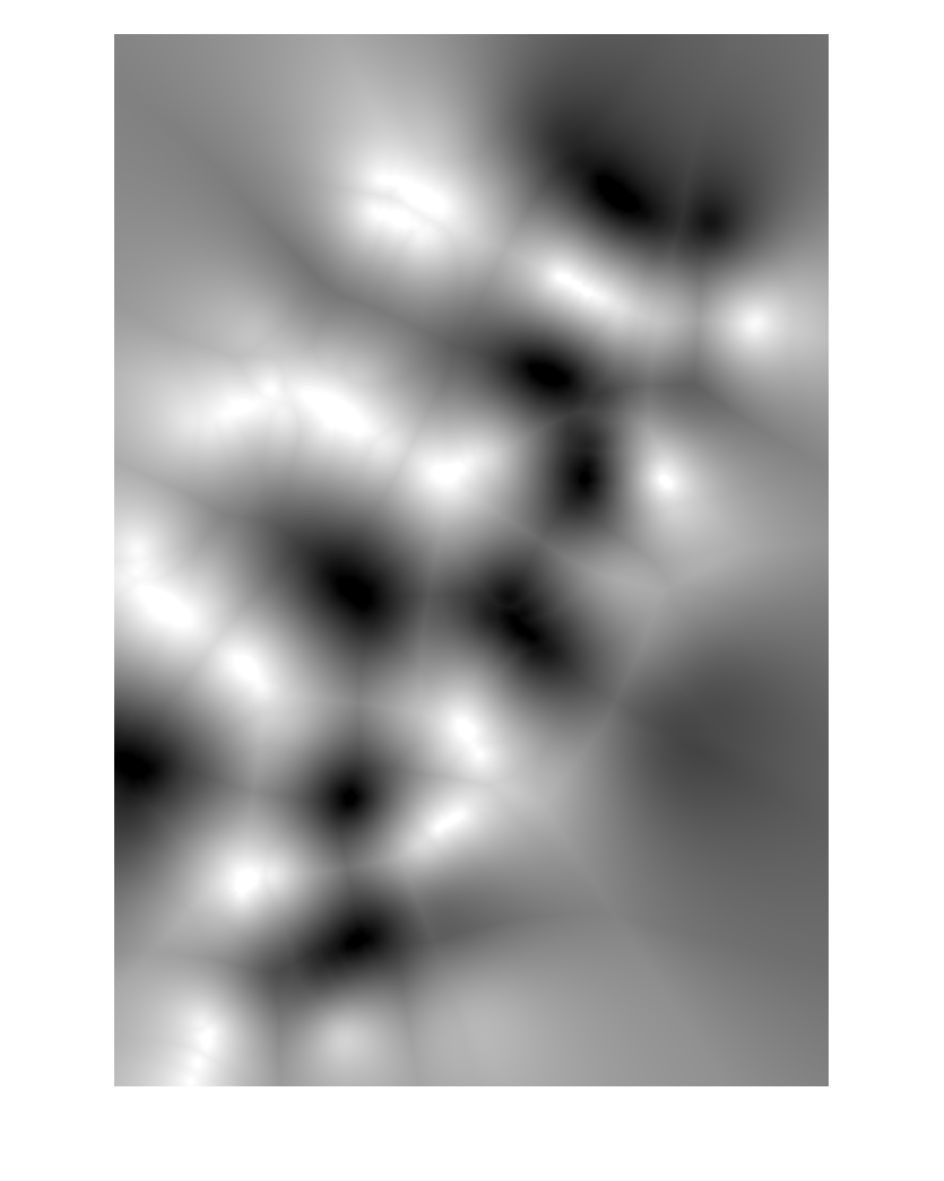

scaled_ratio = multichannel(:, :, :, 7);
imshow(scaled_ratio(:, :, 80));

% centroid --> DR
x = round(table.Centroid_1); % regionprops use xyz
y = round(table.Centroid_2);
z = round(table.Centroid_3);
ratio_list = zeros(height(table), 1);

for i = 1:height(table)
    ratio_list(i) = scaled_ratio(y(i), x(i), z(i));
end

table = addvars(table, ratio_list, 'Before', 2, 'NewVariableNames', 'DistanceRatio');
table = removevars(table, {'Centroid_1', 'Centroid_2', 'Centroid_3'});

% eigenvalue --> eccentricity
eccentricity = sqrt(1 - table.EigenValues_3 ./ table.EigenValues_1);
table = addvars(table, eccentricity, 'Before', 4, 'NewVariableNames', 'eccentricity');
table = removevars(table, {'EigenValues_1', 'EigenValues_2', 'EigenValues_3'});

% filter 0 nuclei (keep for now)
filtered_table = table;
filtered_table = table(table.NumNuclei ~= 0, :);
writetable(filtered_table, outname);

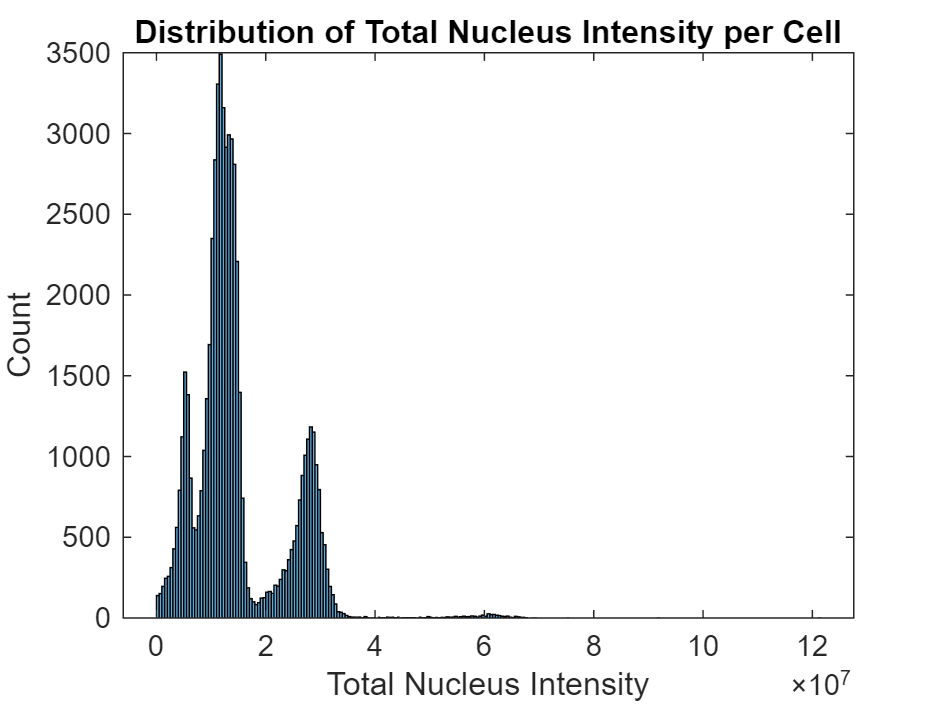

% intensity
figure;
histogram(filtered_table.TotalNucleusIntensity);
xlabel('Total Nucleus Intensity');
ylabel('Count');
title('Distribution of Total Nucleus Intensity per Cell');

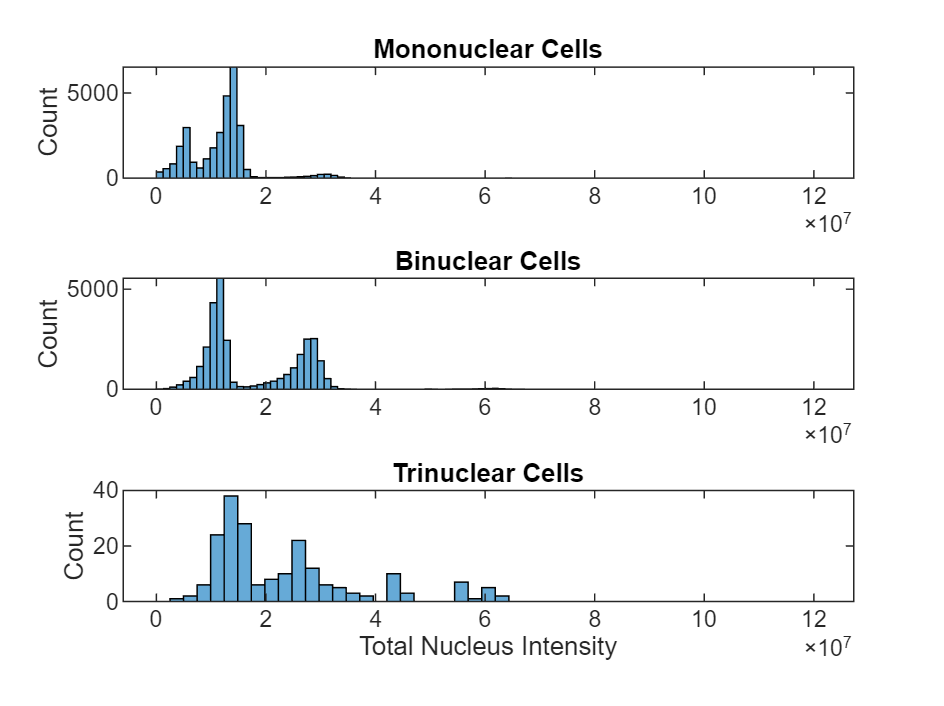

figure;

% Define bins for mono/binuclear
all_intensities = filtered_table.TotalNucleusIntensity;
nbins = 100;  % for mono and binuclear
edges = linspace(min(all_intensities), max(all_intensities), nbins);

% Define fewer bins for multinuclear
nbins_tri = 50;  % half the bins for multinuclear
edges_tri = linspace(min(all_intensities), max(all_intensities), nbins_tri);

% Plot in three separate subplots
subplot(3,1,1)
histogram(filtered_table.TotalNucleusIntensity(filtered_table.NumNuclei == 1), edges)
title('Mononuclear Cells')
ylabel('Count')

subplot(3,1,2)
histogram(filtered_table.TotalNucleusIntensity(filtered_table.NumNuclei == 2), edges)
title('Binuclear Cells')
ylabel('Count')

subplot(3,1,3)
histogram(filtered_table.TotalNucleusIntensity(filtered_table.NumNuclei == 3), edges_tri)
title('Trinuclear Cells')
xlabel('Total Nucleus Intensity')
ylabel('Count')

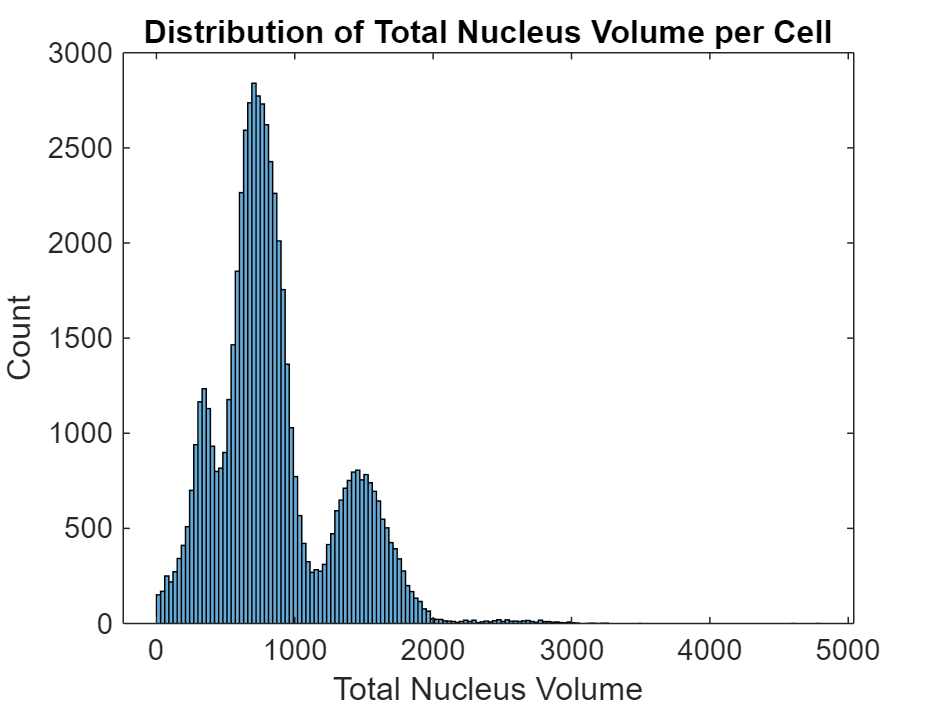

% volume
figure;
histogram(filtered_table.TotalNucleusVolume);
xlabel('Total Nucleus Volume');
ylabel('Count');
title('Distribution of Total Nucleus Volume per Cell');

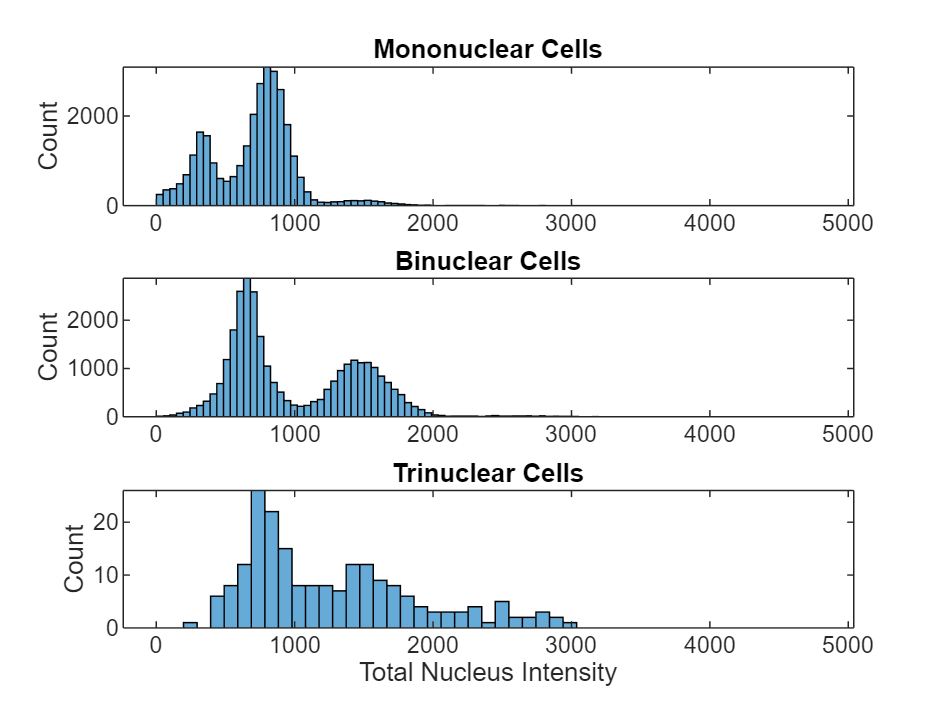

figure;

% Define bins for mono/binuclear
all_volumes = filtered_table.TotalNucleusVolume;
nbins = 100;  % for mono and binuclear
edges = linspace(min(all_volumes), max(all_volumes), nbins);

% Define fewer bins for multinuclear
nbins_tri = 50;  % half the bins for multinuclear
edges_tri = linspace(min(all_volumes), max(all_volumes), nbins_tri);

% Plot in three separate subplots
subplot(3,1,1)
histogram(filtered_table.TotalNucleusVolume(filtered_table.NumNuclei == 1), edges)
title('Mononuclear Cells')
ylabel('Count')

subplot(3,1,2)
histogram(filtered_table.TotalNucleusVolume(filtered_table.NumNuclei == 2), edges)
title('Binuclear Cells')
ylabel('Count')

subplot(3,1,3)
histogram(filtered_table.TotalNucleusVolume(filtered_table.NumNuclei == 3), edges_tri)
title('Trinuclear Cells')
xlabel('Total Nucleus Intensity')
ylabel('Count')